# Start

%% Sparse Antenna Array with Real Physical Elements
clear; clc;

% --- Parameters ---
apertureArea = 14;          % m^2
minDistance = 200;          % Minimum element spacing in meters
numElements = 20;           % Number of elements (keep low for MoM solver speed)
boundarySize = 2000;        % 1km x 1km area
freq = 2.1e9;               % Operating Frequency (e.g., 300 MHz)

# Position

% 1. Generate Sparse Random Positions (Poisson Disc logic)
positions = [];
attempts = 0;
while size(positions, 1) < numElements && attempts < 5000
    candidate = (rand(1, 2) - 0.5) * boundarySize; % Centered at [0,0]
    if isempty(positions)
        positions = candidate;
    else
        distances = sqrt(sum((positions - candidate).^2, 2));
        if all(distances >= minDistance)
            positions = [positions; candidate];
        end
    end
    attempts = attempts + 1;
end

% 2. Create the Physical Element (Circular Disk for 10m^2 aperture)
% Note: Using a large patch/reflector to represent the aperture
radius = sqrt(apertureArea/pi)

radius = 2.1110

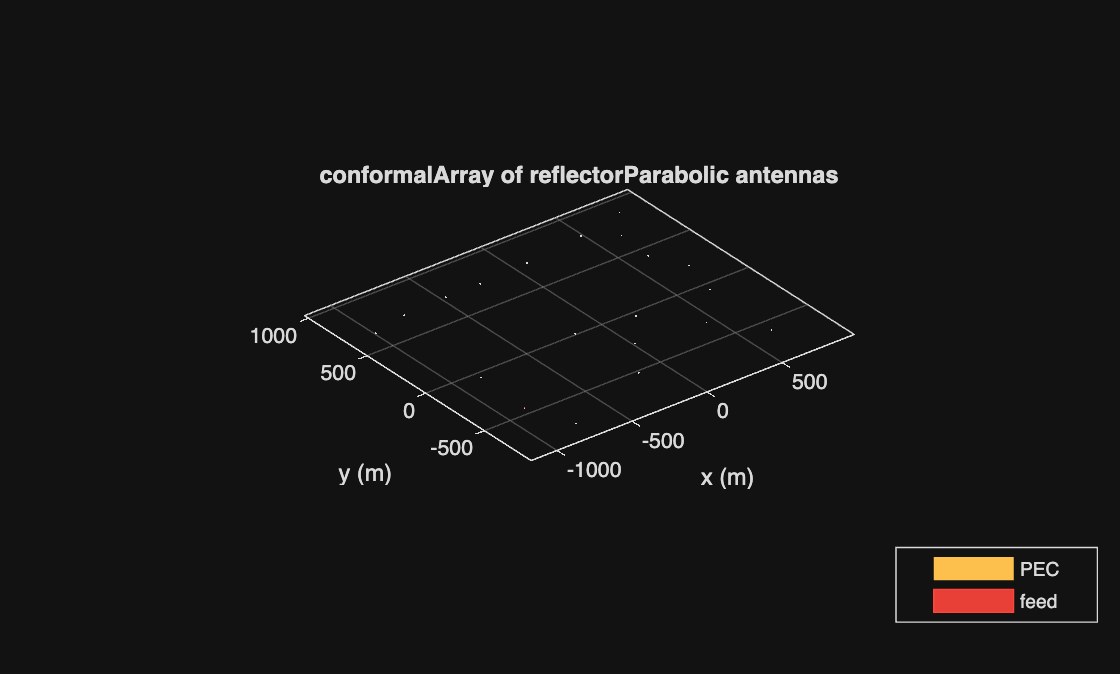

%element = patchMicrostripCircular(Radius=radius, Height=0.05);
element = reflectorParabolic;
element.Radius = radius;
f_D_ratio = 0.4;        
focal_len = radius *2 * f_D_ratio; 
element.FocalLength = focal_len;

% 3. Construct the Conformal Array
% We add a 0 for the Z-coordinate to make them 3D points
zCoords = zeros(size(positions, 1), 1);
xyzPoints = [positions, zCoords];

sparseArray = conformalArray;
sparseArray.Element = element;
sparseArray.ElementPosition = xyzPoints;

% 4. Visualize like Antenna Designer
figure('Name', 'Sparse Array Layout');
title(sprintf('Random Sparse Array: %d Elements', numElements));

% To see the physical elements and their positions
show(sparseArray) 

# Pattern

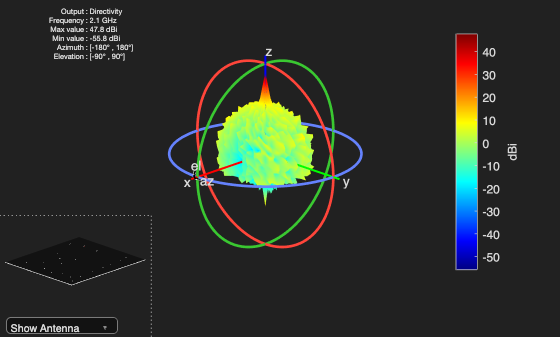

%% To see the 3D radiation pattern (this may take a moment to solve)
% Adjust to your design frequency
patternMultiply(sparseArray, freq)